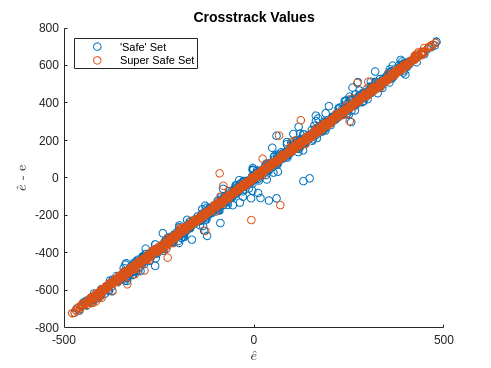

clear variables; close all; clc;

function data = grabData(data_g, data_c)
    data = table;
    data.error_NN_h = data_c.error_h; %NN Error, height offset 
    data.error_NN_y = data_c.error_y; %NN Error, crosstrack offset 
    data.y_pred = data_g.y_err; %NN Output- Predicted crosstrack offset 
    data.h_pred = data_g.h_err_NN; %NN Output- Predicted height offset
    data.h_true = data_g.h_err_true; %True height error based on state info 

    %True State Information 
    data.y = data_c.y;
    data.x = data_c.x; %Horizontal distance from runway 
    data.h = data_c.h; %True Height (Altitude relative to runway) 
end

function maxes = findMaxes(data, x_axis, dist)
    all_max = [];
    all_x = [];
    for start = 1:dist:(length(data) - dist)
        [local_max, index] = max(data(start:(start + dist)));
        all_max(length(all_max) + 1) = local_max;
        all_x(length(all_x) + 1) = x_axis(start + index);
    end
    maxes = [all_x; all_max];
end

function slices = grabSlice(data, start, endpoint)
    rows = data.x > start & data.x <= endpoint;
    slices = data(rows,:);
end

safe_slices_g = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/slices/safe/2024-7-23/generated_states.csv");
safe_slices_c = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/slices/safe/2024-7-23/combined_states.csv");
safe_slices = grabData(safe_slices_g, safe_slices_c);

unsafe_slices_g = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/slices/unsafe/2024-7-23/generated_states.csv");
unsafe_slices_c = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/slices/unsafe/2024-7-23/combined_states.csv");
unsafe_slices = grabData(unsafe_slices_g, unsafe_slices_c);

scatter(unsafe_slices.error_NN_y, unsafe_slices.y_pred);
hold on;
scatter(safe_slices.error_NN_y, safe_slices.y_pred);
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Crosstrack Values");
legend({"'Safe' Set", "Super Safe Set"}, 'Location', 'northwest');
hold off;

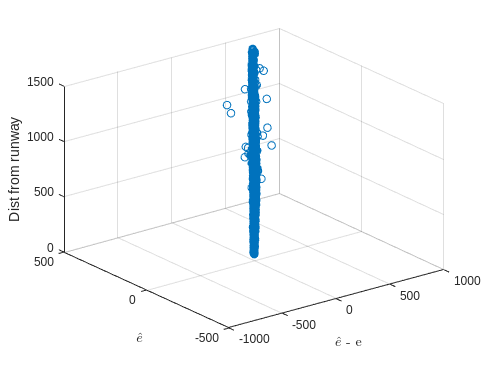


scatter3(safe_slices.y_pred, safe_slices.error_NN_y, safe_slices.x);
zlabel("Dist from runway");
ylabel('$$\hat{e}$$','Interpreter','Latex');
xlabel('$\hat{e}$ - e','Interpreter','Latex');

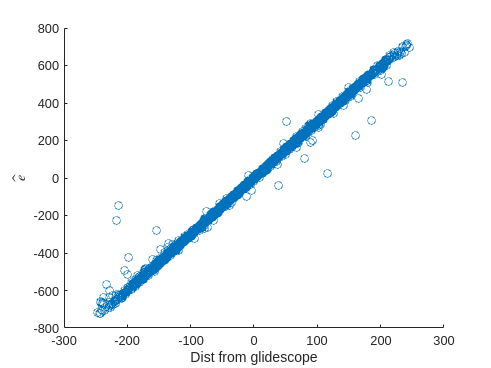


scatter(safe_slices.y, safe_slices.y_pred);
xlabel("Dist from glidescope");
ylabel('$$\hat{e}$$','Interpreter','Latex');

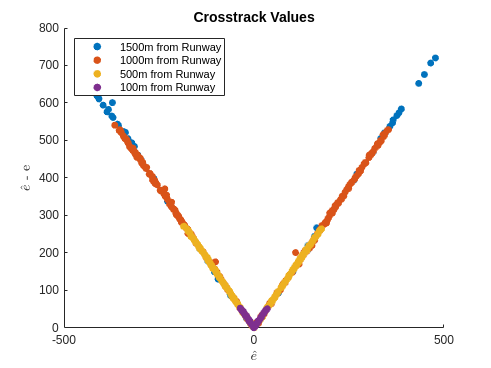


safe_slice_100 = grabSlice(safe_slices, 0, 100);
safe_slice_500 = grabSlice(safe_slices, 400, 500);
safe_slice_1000 = grabSlice(safe_slices, 900, 1000);
safe_slice_1500 = grabSlice(safe_slices, 1400, 1500);

unsafe_slice_100 = grabSlice(unsafe_slices, 0, 100);
unsafe_slice_500 = grabSlice(unsafe_slices, 400, 500);
unsafe_slice_1000 = grabSlice(unsafe_slices, 900, 1000);
unsafe_slice_1500 = grabSlice(unsafe_slices, 1400, 1500);

scatter(safe_slice_1500.error_NN_y, abs(safe_slice_1500.y_pred), 30, "filled");
hold on;
scatter(safe_slice_1000.error_NN_y, abs(safe_slice_1000.y_pred), 30, "filled");
scatter(safe_slice_500.error_NN_y, abs(safe_slice_500.y_pred), 30, "filled");
scatter(safe_slice_100.error_NN_y, abs(safe_slice_100.y_pred), 30, 'filled');
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Crosstrack Values");
legend({"1500m from Runway", "1000m from Runway", "500m from Runway", "100m from Runway"}, 'Location', 'northwest');
hold off;

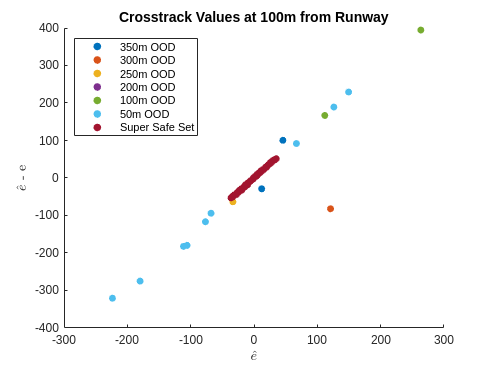



csvDataSafe_g = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/safe/2024-7-19/generated_states.csv");
csvDataSafe_c = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/safe/2024-7-19/combined_states.csv");
safe = grabData(csvDataSafe_g, csvDataSafe_c);

csvDataUnsafe_g = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/unsafe/2024-7-19/generated_states.csv"); %50m, OOD by 0
csvDataUnsafe_c = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/unsafe/2024-7-19/combined_states.csv");
unsafe = grabData(csvDataUnsafe_g, csvDataUnsafe_c);

csv_50_g = readtable("/home/achadbo/XPlaneAutolandScenario/errors/2024-7-22/50/generated_states.csv");
csv_50_c = readtable("/home/achadbo/XPlaneAutolandScenario/plots/2024-7-22/50/combined_states.csv");
data_50 = grabData(csv_50_g, csv_50_c);

csv_100_g = readtable("/home/achadbo/XPlaneAutolandScenario/errors/2024-7-22/100/generated_states.csv");
csv_100_c = readtable("/home/achadbo/XPlaneAutolandScenario/plots/2024-7-22/100/combined_states.csv");
data_100 = grabData(csv_100_g, csv_100_c);

csv_200_g = readtable("/home/achadbo/XPlaneAutolandScenario/errors/2024-7-22/200/generated_states.csv");
csv_200_c = readtable("/home/achadbo/XPlaneAutolandScenario/plots/2024-7-22/200/combined_states.csv");
data_200 = grabData(csv_200_g, csv_200_c);

csv_250_g = readtable("/home/achadbo/XPlaneAutolandScenario/errors/2024-7-22/250/generated_states.csv");
csv_250_c = readtable("/home/achadbo/XPlaneAutolandScenario/plots/2024-7-22/250/combined_states.csv");
data_250 = grabData(csv_250_g, csv_250_c);

csv_300_g = readtable("/home/achadbo/XPlaneAutolandScenario/errors/2024-7-22/300/generated_states.csv");
csv_300_c = readtable("/home/achadbo/XPlaneAutolandScenario/plots/2024-7-22/300/combined_states.csv");
data_300 = grabData(csv_300_g, csv_300_c);

csv_350_g = readtable("/home/achadbo/XPlaneAutolandScenario/errors/2024-7-22/350/generated_states.csv");
csv_350_c = readtable("/home/achadbo/XPlaneAutolandScenario/plots/2024-7-22/350/combined_states.csv");
data_350 = grabData(csv_350_g, csv_350_c);

csv_400_g = readtable("/home/achadbo/XPlaneAutolandScenario/errors/2024-7-22/400/generated_states.csv");
csv_400_c = readtable("/home/achadbo/XPlaneAutolandScenario/plots/2024-7-22/400/combined_states.csv");
data_400 = grabData(csv_400_g, csv_400_c);


ood_100_100 = grabSlice(data_100, 99, 100);
ood_200_100 = grabSlice(data_200, 99, 100);
ood_250_100 = grabSlice(data_250, 99, 100);
ood_300_100 = grabSlice(data_300, 99, 100);
ood_350_100 = grabSlice(data_350, 99, 100);
ood_400_100 = grabSlice(data_400, 99, 100);

scatter(ood_400_100.error_NN_y, (ood_400_100.y_pred), 30, 'filled');
hold on;
scatter(ood_350_100.error_NN_y, (ood_350_100.y_pred), 30, 'filled');
scatter(ood_300_100.error_NN_y, (ood_300_100.y_pred), 30, 'filled');
scatter(ood_250_100.error_NN_y, (ood_250_100.y_pred), 30, 'filled');
scatter(ood_200_100.error_NN_y, (ood_200_100.y_pred), 30, 'filled');
scatter(ood_100_100.error_NN_y, (ood_100_100.y_pred), 30, 'filled');
scatter(safe_slice_100.error_NN_y, (safe_slice_100.y_pred), 30, 'filled');
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Crosstrack Values at 100m from Runway");
legend({"350m OOD", "300m OOD", "250m OOD", "200m OOD", "100m OOD", "50m OOD", "Super Safe Set"}, 'Location', 'northwest');
hold off;

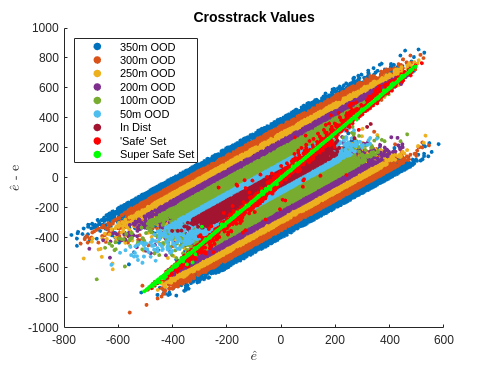


% data_50 = sortrows(data_50, "error_NN_y");
% max_100 = findMaxes(data_50.y_pred, data_50.error_NN_y, 100);
% 
% scatter(max_100(1,:), max_100(2,:));

size = 10;
scatter(data_400.error_NN_y, (data_400.y_pred), size, "filled");
hold on;
scatter(data_350.error_NN_y, (data_350.y_pred), size, "filled");
scatter(data_300.error_NN_y, (data_300.y_pred), size, "filled");
scatter(data_250.error_NN_y, (data_250.y_pred), size, "filled");
scatter(data_200.error_NN_y, (data_200.y_pred), size, "filled");
scatter(data_100.error_NN_y, (data_100.y_pred), size, "filled");
scatter(data_50.error_NN_y, (data_50.y_pred), size, "filled");
scatter(unsafe.error_NN_y, (unsafe.y_pred), size, "red", "filled");
scatter(safe.error_NN_y, (safe.y_pred), size, "green", "filled");
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Crosstrack Values");
legend({"350m OOD", "300m OOD", "250m OOD", "200m OOD", "100m OOD", "50m OOD", "In Dist", "'Safe' Set", "Super Safe Set"}, 'Location', 'northwest');
hold off;

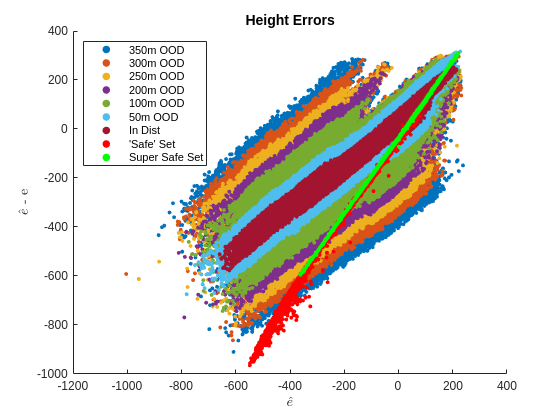


scatter(data_400.error_NN_h, data_400.h_pred, size, "filled");
hold on; 
scatter(data_350.error_NN_h, data_350.h_pred, size, "filled");
scatter(data_300.error_NN_h, data_300.h_pred, size, "filled");
scatter(data_250.error_NN_h, data_250.h_pred, size, "filled");
scatter(data_200.error_NN_h, data_200.h_pred, size, "filled");
scatter(data_100.error_NN_h, data_100.h_pred, size, "filled");
scatter(data_50.error_NN_h, data_50.h_pred, size, "filled");
scatter(unsafe.error_NN_h, unsafe.h_pred, size, "red", "filled");
scatter(safe.error_NN_h, safe.h_pred, size, "green", "filled");
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Height Errors");
legend({"350m OOD", "300m OOD", "250m OOD", "200m OOD", "100m OOD", "50m OOD", "In Dist", "'Safe' Set", "Super Safe Set"}, 'Location', 'northwest');
hold off;


% scatter3(x_unsafe, y_pred_unsafe, error_NN_y_unsafe);
% hold on;
% scatter3(x_safe, y_pred_safe, error_NN_y_safe);
% xlabel("Dist from Runway")
% ylabel('$$\hat{e}$$','Interpreter','Latex');
% zlabel('$\hat{e}$ - e','Interpreter','Latex');
% legend({"'Safe' Set", "Super Safe Set"}, 'Location', 'northwest');
% hold off;
% 
% scatter3(x_unsafe, h_pred_unsafe, error_NN_h_unsafe);
% hold on;
% scatter3(x_safe, h_pred_safe, error_NN_h_safe);
% xlabel("Dist from Runway")
% ylabel('$$\hat{e}$$','Interpreter','Latex');
% zlabel('$\hat{e}$ - e','Interpreter','Latex');
% legend({"'Safe' Set", "Super Safe Set"}, 'Location', 'northwest');
% title("H-errors");
% hold off;
